# Human vs Machine Learning

Let's take a closer look at the difference between how we learn as humans and how machines learn.

Consider this relation between two variables, $x$ and $y$. 

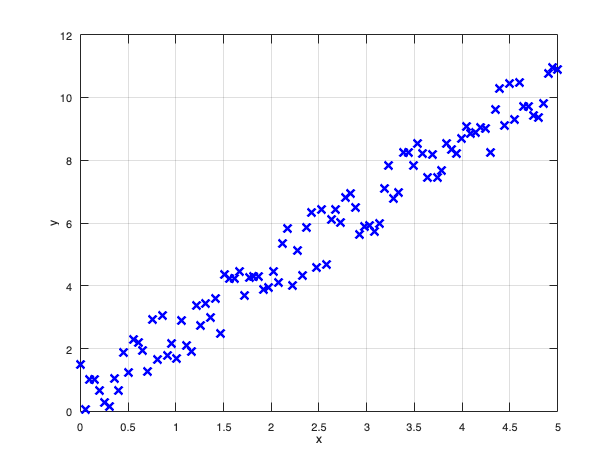

clear; clf; 
m = 2; b = 0.5;
x = linspace(0,5,100);
y = addrandomfluctuations(x,m,b,2);
plot(x,y,'bx','MarkerSize',10, 'LineWidth',2)
xlabel('x'); ylabel('y');
% axis([0 0.5 0 2])
grid on

*Figure 1.1. A data set that forms a straight line. But the computer doesn't know it's a straight line.*

## How we determine the best fit line

We know instinctively that this data forms a straight line, even though there's a little bit of randomness in the line. We know that we can plot a straight line that will represent this data. The straight line that fits this data set is given by $y=mx+b$, where $m$ is the slope and $b$ is the y-intercept. We can get the slope and the y-intercept using three methods. The first is we get a ruler and we draw a line that roughly passes through these points. We see that it intersects the y-axis at some point and we call that point our y-intercept. Then, we count the number of grid lines that represents the rise along the y-axis and the run along the x-axis to estimate the slope. The second method is we estimate the error between these data points and the expected value, represented by the equation of a line, and we minimize that error by doing some calculus. Minimizing gives us the slope and the y-intercept. We know this because these are the rules that mathematics taught us. 

Of course, the third method is to use the tools available to us in MATLAB.

p = polyfit(x,y,1)

p =     2.0401    0.4390


ylr = addrandomfluctuations(x,p(1),p(2),0.0)

ylr =     0.4390    0.5420    0.6451    0.7481    0.8511    0.9542    1.0572    1.1602    1.2633    1.3663    1.4693    1.5724    1.6754    1.7785    1.8815    1.9845    2.0876    2.1906    2.2936    2.3967    2.4997    2.6027    2.7058    2.8088    2.9118    3.0149    3.1179    3.2209    3.3240    3.4270    3.5301    3.6331    3.7361    3.8392    3.9422    4.0452    4.1483    4.2513    4.3543    4.4574    4.5604    4.6634    4.7665    4.8695    4.9726    5.0756    5.1786    5.2817    5.3847    5.4877


To get a better perspective of how the *polyfit* function fares with the actual result, we plot the *polyfit* prediction against the data points.

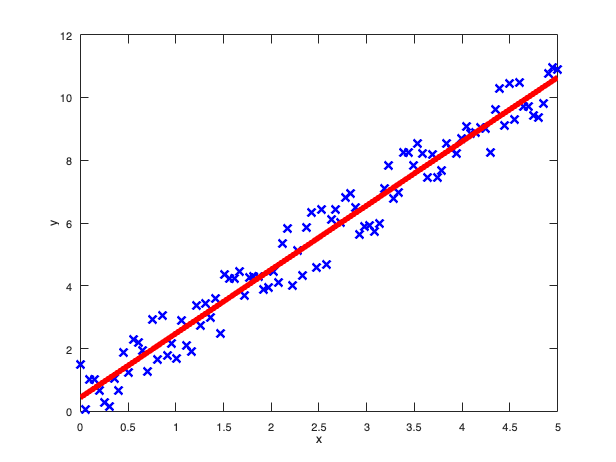

plot(x,y,'bx','MarkerSize',10, 'LineWidth',2)
hold on
plot(x,ylr, 'r', 'LineWidth',5)
xlabel('x'); ylabel('y');
% axis([0 0.5 0 2])
hold off

*Figure 1.2. Predicted best fit line using the linear regression algorithm of MATLAB.*

As you can see from the code, the MATLAB built-in function *polyfit* provides a numerical value for the slope and the y-intercept in the variable $p$, where the first element is the slop and the second element is the y-intercept. 

p

p =     2.0401    0.4390


We can compare that to the given $m=2$ and $b=0.5$. We can further estimate the error of $y$ for a given value of $x$ based on the data. 

ytest = p(1)*x + p(2);

Using $m=2$ and $b=0.5$, we find that the true value is 

ytrue = m*x + b;

We solve for the error to be

error = 100*abs(ytrue-ytest)/ytrue

error = 1.0696

MSE = mean(error.^2)

MSE = 1.1440

An alternative solution is shown below using the function fitlm().

% % use linear regression to determine the best fit
% model = fitlm(x,y)
% 
% % display the computed coefficients
% model.Coefficients
% 
% % extract the slope and yintercept to the variables
% yintercept = model.Coefficients.Estimate(1,1)
% slope = model.Coefficients.Estimate(2,1)
% 
% % generate the y data set from linear regression
% ylr = model.Fitted;
% 
% plot(x,y,'bx','MarkerSize',10, 'LineWidth',2)
% hold on
% plot(x,ylr, 'r', 'LineWidth',5)
% xlabel('x'); ylabel('y');
% hold off

*Figure 1.2. Predicted best fit line using the linear regression algorithm of MATLAB.*

## How a computer determines the best fit line

A computer doesn't know any of these rules. What the computer does after it gets the data is that it'll make several guesses for the slope and the y-intercept until the error becomes really small. In each guess, it rewrites some parameters that it uses so that the error becomes smaller and smaller. When the error is small enough, then the computer returns the final value of the slope and the y-intercept to represent the line. After all of that, the computer still doesn't know what the mathematical rules are.

This short code is a machien learning model that will solve for the best fit line of the given data $x$ and $y$.

% Alternative 1
layers = [
    sequenceInputLayer(1,"MinLength",length(x))
    fullyConnectedLayer(1)
    regressionLayer
    ];
options = trainingOptions("sgdm","MaxEpochs",100,...
    "InitialLearnRate",0.0001,...
    "Plots","training-progress")

options =   TrainingOptionsSGDM with properties:

                        Momentum: 0.9000
                InitialLearnRate: 1.0000e-04
                       MaxEpochs: 100
               LearnRateSchedule: 'none'
             LearnRateDropFactor: 0.1000
             LearnRateDropPeriod: 10
                   MiniBatchSize: 128
                         Shuffle: 'once'
                      WorkerLoad: []
             CheckpointFrequency: 1
         CheckpointFrequencyUnit: 'epoch'
                  SequenceLength: 'longest'
            DispatchInBackground: 0
                L2Regularization: 1.0000e-04
         GradientThresholdMethod: 'l2norm'
               GradientThreshold: Inf
                         Verbose: 1
                VerboseFrequency: 50
                  ValidationData: []
             ValidationFrequency: 50
              ValidationPatience: Inf
                  CheckpointPath: ''


Training on single CPU.
|========================================================================================|
|  Epoch  |  Iteration  |  Time Elapsed  |  Mini-batch  |  Mini-batch  |  Base Learning  |
|         |             |   (hh:mm:ss)   |     RMSE     |     Loss     |      Rate       |
|========================================================================================|
|       1 |           1 |       00:00:01 |        10.89 |         59.3 |      1.0000e-04 |
|      50 |          50 |       00:00:01 |         0.87 |          0.4 |      1.0000e-04 |
|     100 |         100 |       00:00:01 |         0.58 |          0.2 |      1.0000e-04 |
|========================================================================================|
Training finished: Max epochs completed.


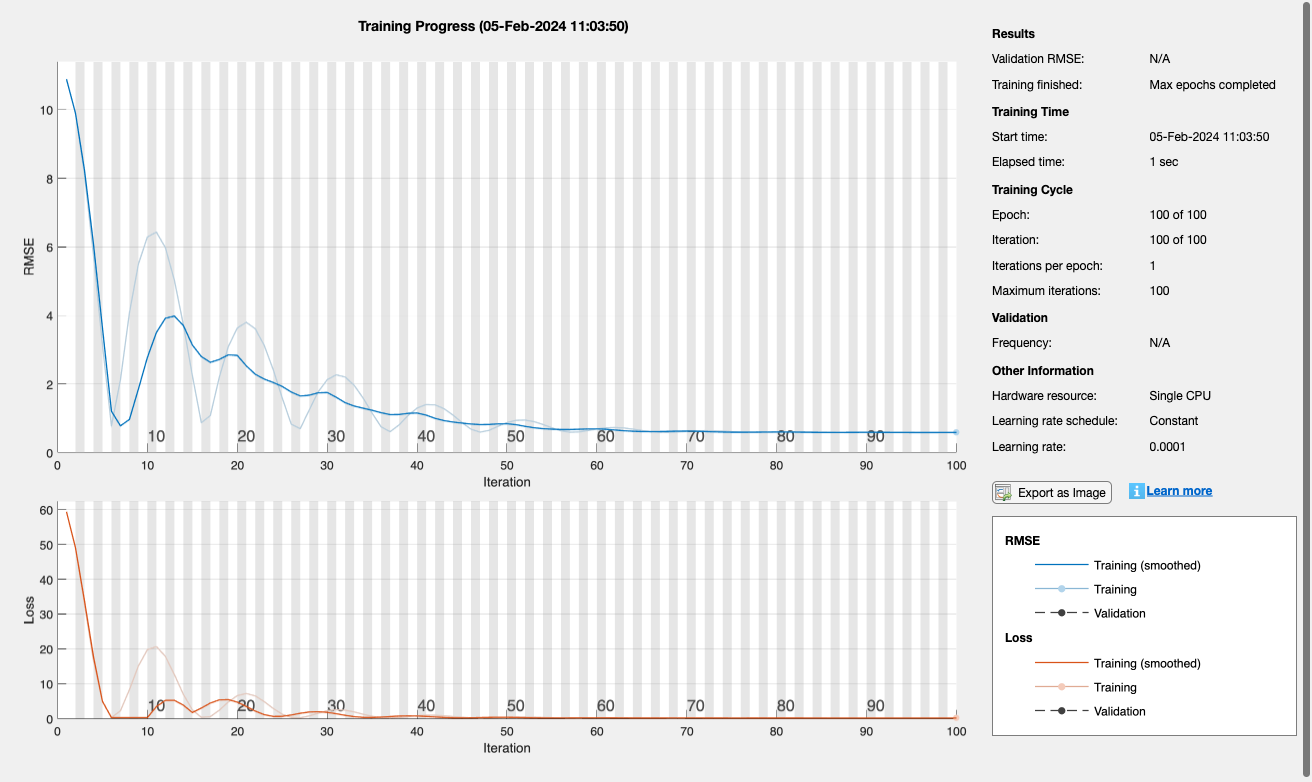

net = trainNetwork(x,y,layers,options);

*Figure 1.3. Training progress of the model.*

This is the prediction of the slope and the y-intercept based on the model. The Learnable Parameters, Weights and Bias, are the calculated slope and y-intercept, respectively, calculated by the model.

net.Layers(2,1).Weights

ans = single
2.0155

net.Layers(2,1).Bias

ans = single
0.4716

This is the prediction of the best-fit line based on the model.

ymach = net.predict(x)

ymach = 1×100 single row vector
    0.4264    0.5295    0.6325    0.7356    0.8387    0.9417    1.0448    1.1478    1.2509    1.3540    1.4570    1.5601    1.6631    1.7662    1.8693    1.9723    2.0754    2.1784    2.2815    2.3846    2.4876    2.5907    2.6937    2.7968    2.8999    3.0029    3.1060    3.2090    3.3121    3.4152    3.5182    3.6213    3.7243    3.8274    3.9305    4.0335    4.1366    4.2396    4.3427    4.4458    4.5488    4.6519    4.7549    4.8580    4.9611    5.0641    5.1672    5.2702    5.3733    5.4764


To get a better perspective of how the model fares with the actual result, we plot the machine learning prediction against the data points.

plot(x,y,'bx','MarkerSize',10, 'LineWidth',2)
hold on
plot(x,ymach, 'r', 'LineWidth',5)
xlabel('x'); ylabel('y');
hold off

*Figure 1.4. Predicted best fit line by the machine learning model.*

Based on the true value, we solve for the error to be

error = 100*abs(ytrue-ymach)/ytrue

error = single
0.9583

MSE = mean(error.^2)

MSE = single
0.9184

#### Why are we still solving for the error even if the calculations were performed by a computer? 

#### As you will soon learn, computers learn based on statistical techniques, which is why their guesses will not always be exact. To a computer, the result indicated by the red line in the graph is the most probable result from the given data.

% % Alternative 2
% net = fitnet(1,'trainscg');  %% algorithm is a scaled conjugate gradient
%                              %% with gradient descent ('traingd') and gradient descent with momentum ('traingdm')
%                              %% the fittings are non-linear
% % view(net);
% [net,tr] = train(net,x,y);
% view(net);
% ypred = net(x);             %% solves for the predicted value given the x data
% perf = perform(net,x,y);    %% solves for the mean-squared error
% 
% xtest = 3
% ytest = net(xtest)
% ytrue = m*xtest + b
% error = 100*abs(ytrue-ytest)/ytrue
% MSE = mean(error.^2)

## Functions Used

This is the function that adds a random-sized vertical amplitude at each data point to make the data set look randomized.

function yrand = addrandomfluctuations(x,m,b,fluctuationsize)

    for i = 1:length(x)
        yrand(i) = m*x(i) + b + fluctuationsize*(rand(1)-0.5);
    end

end